# MVP CPR Frequency Analysis

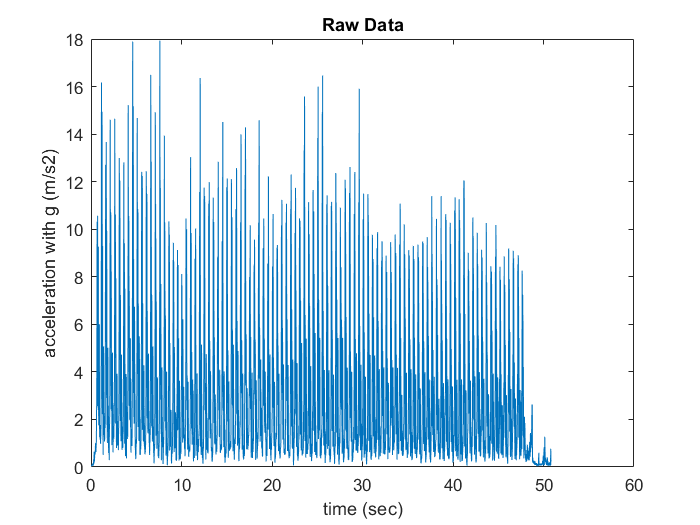

clear
[numbers, strings, raw] = xlsread("dummy1.xls");

% import first and last column of xls data as double
accel = numbers(:,5);
time = numbers(:,1);

% plot time domain data
figure(1)
plot(time,accel)
title("Raw Data")
xlabel("time (sec)")
ylabel("acceleration with g (m/s2)")

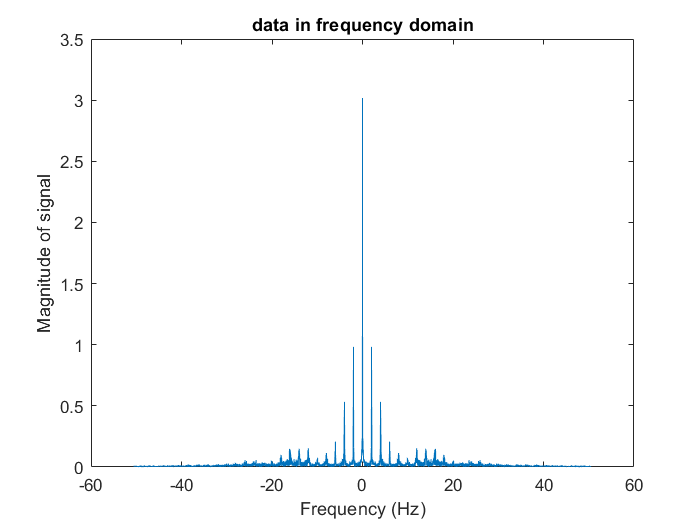

   -0.0000   -1.9932    1.9932



amp = 0.9821

freq = 1.9932

offset_amp = 3.0170



% total number of samples
N = length(time); 
% sampling rate: 
Fs = round(N/time(end)); % # of samples per time(sec)

% perform DFT to calculate overall CPR frequency
% amp: max amplitude
% freq: dominant frequency (Hz)
[amp, freq, offset_amp] = make_freq_plot_max(accel,Fs)

freq_bpm = freq * 60; % convert from Hz to bpm

% data segmentation to calculate consistency
seg_time = 5;
i_start = 1;
seg_number = 1;
[~, i_length] = min(abs(time - seg_time));
i_end = i_start + i_length;
overlap_i = 100

overlap_i = 100

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120

         0   -2.0120    2.0120



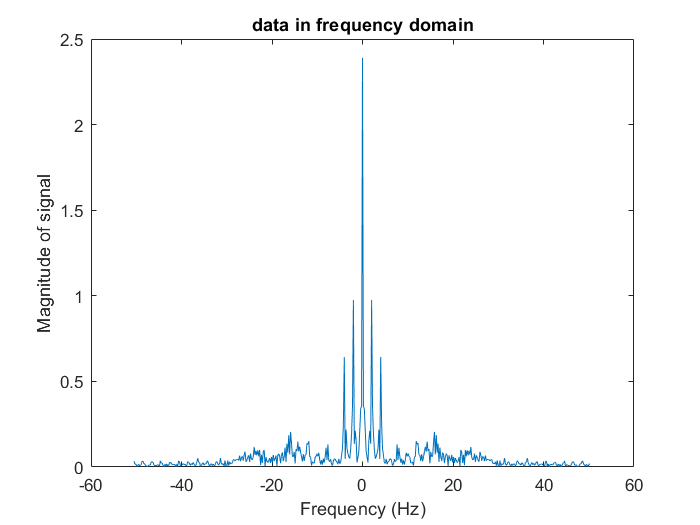

         0   -2.0120    2.0120




while i_end <= length(time)
time_list(:,seg_number) = time(i_start:i_end);
data_list(:,seg_number) = accel(i_start:i_end);
i_start = i_end - overlap_i;
i_end = i_start + i_length;
seg_number = seg_number + 1;
end 

amp_list = [];
freq_list = [];
for col = 1: size(time_list,2)
    data_part = data_list(:,col);
    [amp_part,freq_part,offset_amp_2] = make_freq_plot_max(data_part,Fs);
    amp_list(end+1) = max(amp_part);
    freq_list(end+1:end + length(freq_part)) = freq_part;
    %freq_list(end+1) = freq_part;
    amp_consistency = std(amp_list);
    freq_consistency = std(freq_list);  
end


if freq_consistency < 0.5 && amp_consistency < 0.5
    disp("good consistency:)")
    consistency_coeff = 1;
elseif freq_consistency < 1.5 && amp_consistency < 1.5
    disp("improve your consistency to do better!")
    consistency_coeff = 0.85;
else
    disp("bad consistency: (")
    consistency_coeff = 0.7;
    isoutlier(freq_list)
end

good consistency:)



% calculate push force score

ideal_distance_low = 3.81; % cm
ideal_distance_high = 5.08; % cm
T_diff = 0.5 * (1 / freq); % sec
disp(offset_amp)

    3.0170



avg_amp = offset_amp + amp / 2 % approx accel of CPR

avg_amp = 3.5081

change_postion = 100 * (0.5 * avg_amp * T_diff ^ 2) / 2; % cm

% calculate push force score
if change_postion <= 6 && change_postion >= 5
    score_a = 100;
    disp("Depth within range!")
elseif change_postion > 6
    score_a = 100 - (change_postion - 6) / 6 * 100;
    disp("Compression depth too large: Pushed too hard!")
    disp(score_a)
elseif change_postion < 5
    score_a = 100 - (5 - change_postion) / 5 * 100;
    disp("Compression depth too small: Push harder!")
else
    score_a = 0;
    disp("none")
end 

Depth within range!



% calculate push freq score
if freq_bpm <= 120 && freq_bpm >= 100
    score_fr = 100;
    disp("Good job!")
elseif freq_bpm > 120
    score_fr = 100 - (freq_bpm - 120) / 120 * 100;
    disp("That was too fast!")
elseif freq_bpm < 100
    score_fr = 100 - (100 - freq_bpm) / 100 * 100;
    disp("That was too slow!")
end 

Good job!



% total score
 score = score_a * 0.25 + score_fr * 0.75;

%round up to 3 sig-figs
score = round(score,1);
score = consistency_coeff * score;
disp("Your score is: " + score)

Your score is: 100



if score < 50
    disp("Try again!")
end